# Basic Tight-Binding Theory - Part 4

## Example 4: The graphene lattice

While the graphene lattice has two sites per unit cell, it is not because there are two distinct atoms (all atoms in the system are Carbon atoms), rather because the honey-comb lattice is not a Bravais lattice; it cannot be constructed with a unit cell of one site. However, it can be constructed by merging two triangular Bravais sublattices (A and B sublattices). This is the reason for why we describe the graphene lattice as having two sites per unit cell. The primitive vectors of the Graphene lattice are as follows


$$\[
\mathbf{a}_1 = (3a/2, \sqrt{3} a/2, 0),\ \mathbf{a}_2 = (3a/2, -\sqrt{3} a/2, 0)
\]
\[
\mathbf{b}_1 = \biggl(\frac{2\pi}{3 a},\frac{2\pi\sqrt{3}}{3 a},0\biggl),\ \mathbf{a}_2 = \biggl(\frac{2\pi}{3 a},\frac{-2\pi\sqrt{3}}{3 a},0\biggl)
\]$$


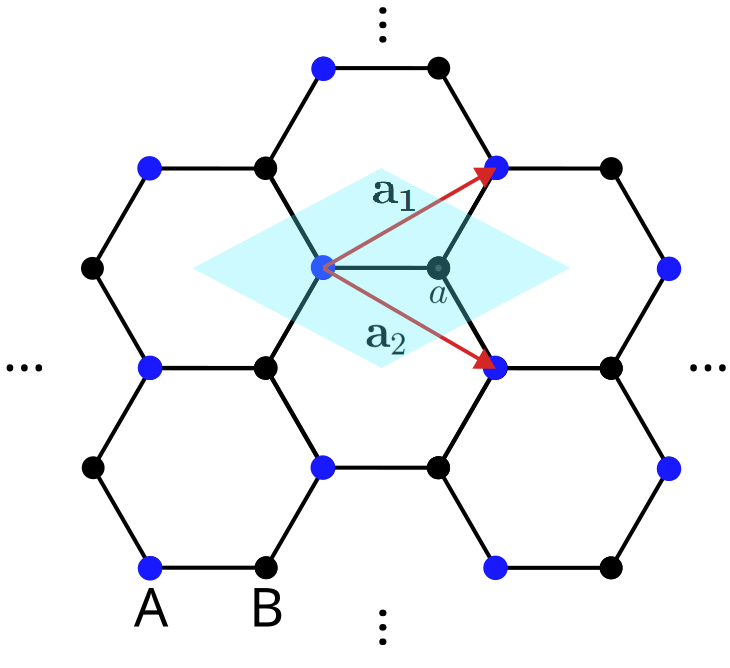

The first Brillouin zone is the area limited by $K_1\rightarrow K_6$:

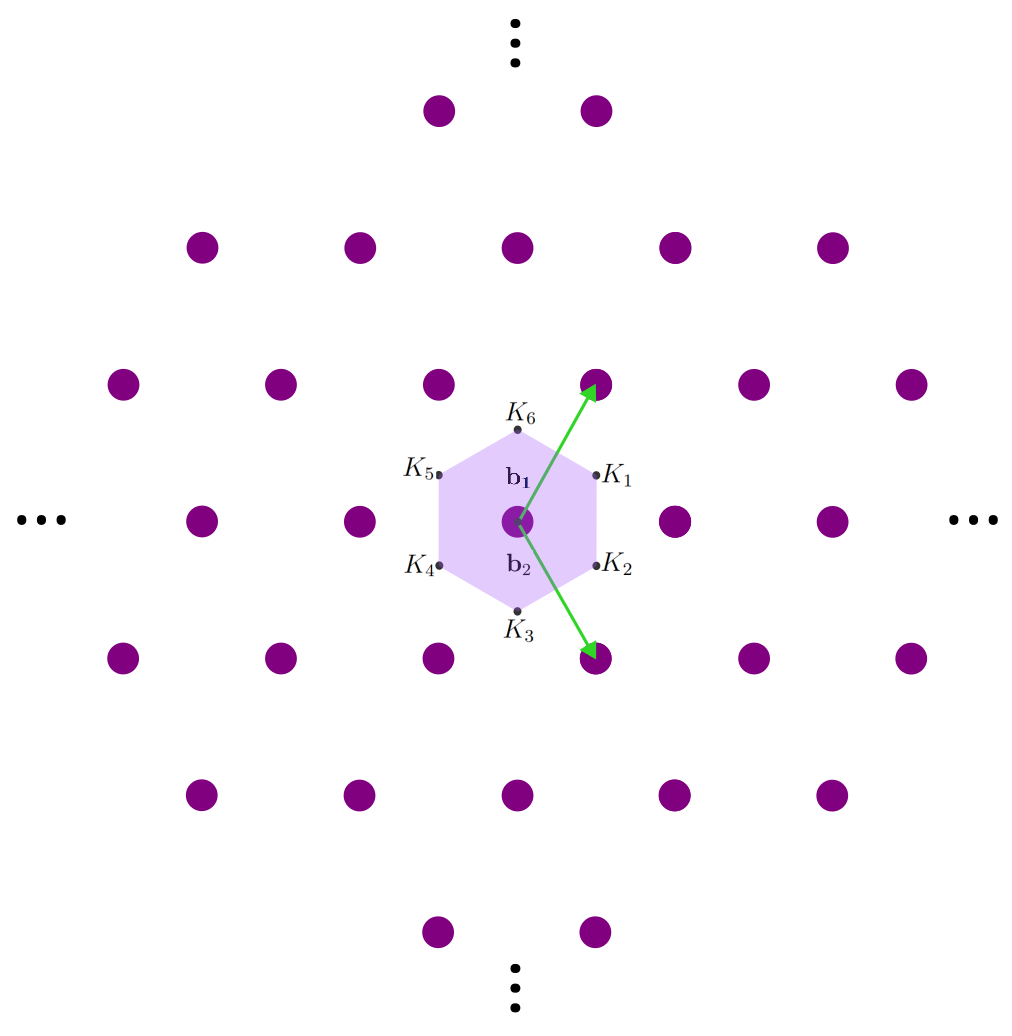


$$
\[
K_1 = \biggl(\frac{2\pi}{3a}, \frac{2\pi}{3\sqrt{3} a}, 0\biggl);\  K_2 = \biggl(\frac{2\pi}{3a}, \frac{-2\pi}{3\sqrt{3} a}, 0\biggl);\ K_3 = \biggl(0, \frac{-4\pi}{3\sqrt{3} a}, 0\biggl);\\
K_4 = \biggl(\frac{-2\pi}{3a}, \frac{-2\pi}{3\sqrt{3} a}, 0\biggl);\  K_5 = \biggl(\frac{-2\pi}{3a}, \frac{2\pi}{3\sqrt{3} a}, 0\biggl);\ K_6 = \biggl(0, \frac{4\pi}{3\sqrt{3} a}, 0\biggl).
\]$$


Now, we define the NN vectors $\{\mathbf{d}_n\}$, for which there are three NNs


$$\[
\mathbf{d}_1 = (a,0,0),\ \mathbf{d}_2 = (-a/2,a\sqrt{3}/2,0),\ \mathbf{d}_3 = (-a/2, -a\sqrt{3}/2,0) 
\]$$


Writing down the Hamiltonian 


$$\[
H = u_A \sum_i a_i^\dag a_i + u_B \sum_j b_j^\dag b_j + t \sum_{i, j} (a_i^\dag b_j+ \textbf{h.c.})
\]$$


Like we did before, changing basis to $k$-space, and setting $u_A = u_B = u$, we get 


$$\[
H = \sum_k 
\left(
\begin{array}{c}
    a_k^\dag & b_k^\dag
\end{array}
\right)
\left(
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\left(
\begin{array}{c}
    a_k \\
    b_k
\end{array}
\right)
\]$$



$$\[
f(\mathbf{k}) \equiv \sum_{n=1}^{3} e^{i(\mathbf{k}\cdot \mathbf{d}_n)} = e^{i(\mathbf{k}\cdot \mathbf{d}_1)} + e^{i(\mathbf{k}\cdot \mathbf{d}_2)} + e^{i(\mathbf{k}\cdot \mathbf{d}_3)} 
= e^{i k_x a} + e^{-i (a/2) k_x} e^{i (\sqrt{3} a/2) k_y} + e^{-i (a/2) k_x} e^{-i (\sqrt{3} a/2) k_y} = e^{i k_x a} + 2 e^{-i (a/2) k_x} \cos\biggl(\frac{\sqrt{3} a}{2} k_y\biggl)\]$$


Evidently,


$$\[
\tilde{H} \equiv
\left( 
\begin{array}{cc}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\]
\[\Rightarrow \det(\tilde{H} - \mathbb{1}E)=
\det\left(
\begin{array}{cc}
    u-E & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u-E
\end{array}
\right)
= (E-u)^2 - t^2 |{f(\mathbf{k})}|^2 \]
\[
= (E-u)^2 - t^2 \biggl|e^{i k_x a} + 2 e^{-i (a/2) k_x} \cos\biggl(\frac{\sqrt{3} a}{2} k_y\biggl)\biggl|^2 = 0
\]
\[
= (E-u)^2 - t^2 \biggr[1 + 2 e^{i 3 k_x a/2} \cos{(\sqrt{3}k_y a/2)}+2 e^{-i 3 k_x a/2} \cos{(\sqrt{3}k_y a/2)} + 4 \cos^2{(\sqrt{3}k_y a/2)}\biggr]
\]
\[
= (E-u)^2 - t^2 \biggr[1 + 4 \biggl(\frac{e^{i 3 k_x a/2} + e^{-i 3 k_x a/2}}{2}\biggl) \cos{(\sqrt{3}k_y a/2)} + 2 \cos{(\sqrt{3}k_y a/2)} + 2\biggr]
\]
\[
= (E-u)^2 - t^2 \biggr[3 + 4 \cos{(3 k_x a/2)} \cos{(\sqrt{3}k_y a/2)} + 2 \cos{(\sqrt{3}k_y a/2)}\biggr]
\]
\[
= (E-u)^2 - t^2 \biggr[3 + 4 \cos{(3 k_x a/2)} \cos{(\sqrt{3}k_y a/2)} + 2 \cos{(\sqrt{3}k_y a/2)}\biggr]
\]
\[
\therefore E(\mathbf{k}) = u \pm t \sqrt{4 \cos{(3 k_x a/2)} \cos{(\sqrt{3}k_y a/2)} + 2 \cos{(\sqrt{3}k_y a/2)}+3}
\]$$


By definition, the high-symmetry points of a graphene lattice are


$$\[
\Gamma = (0,0,0);\ M = \biggl(\frac{2\pi}{3 a}, 0\biggl);\ K = \biggl(\frac{2\pi}{3 a}, \frac{2\pi}{3 \sqrt{3} a}\biggl),
\]$$


and the k-path will be $\Gamma \rightarrow M \rightarrow K \rightarrow \Gamma$.

This time, instead of writig down the eigen-energies in the code, we will make MATLAB find them for us by writing down the Hamiltonian (in $k$-space) and a for loop that inserts a $k$-point in the Hamiltonian and then calculates the eigen-energy at that $k$-point. This is a much more general way of calculating the band structure, especially when dealing with Hamiltonians of larger dimensions.

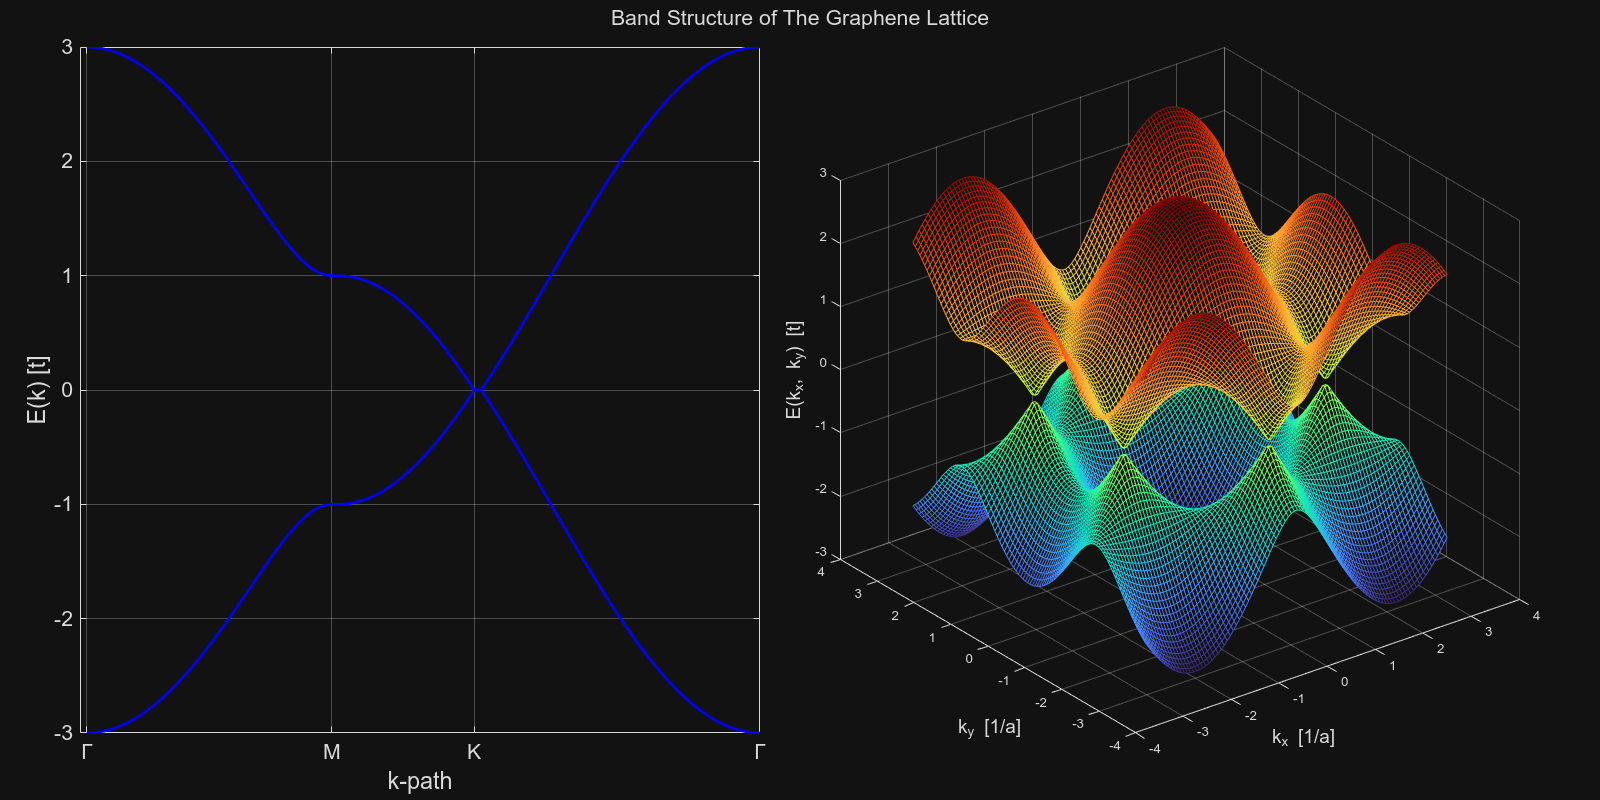

bar = waitbar(0, sprintf('Starting calculations...'));

% Set mesh size
N = 100;

% Set plot color
Colors = "turbo";

% Constants
a = 1; % Set as unit length
t = 1; % Set as unit energy
u = 0; % In units of t

% Define high-symmetry points
kG = [0, 0]; % Γ 
kM = [2*pi/(3*a),0]; % M 
kK = [2*pi/(3*a), 2*pi/(3*sqrt(3)*a)]; % K 

% Calculate lengths of each segment in k-space
lengthGM = norm(kM - kG);
lengthMK = norm(kK - kM);
lengthKG = norm(kG - kK);
totalLength = lengthGM + lengthMK + lengthKG;

% Allocate steps based on relative segment lengths
nGM = round(N * (lengthGM / totalLength));
nMK = round(N * (lengthMK / totalLength));
nKG = N - nGM - nMK;

% Interpolating points along the path
kPathGM = [linspace(kG(1), kM(1), nGM)', linspace(kG(2), kM(2), nGM)'];
kPathMK = [linspace(kM(1), kK(1), nMK)', linspace(kM(2), kK(2), nMK)'];
kPathKG = [linspace(kK(1), kG(1), nKG)', linspace(kK(2), kG(2), nKG)'];
kPath =   [kPathGM; kPathMK; kPathKG];

syms kx ky real

% Define the f_AB, f_BC, and f_CA functions symbolically
f= @(kx,ky) exp(1i*kx*a) + 2*exp(-1i*kx*a/2).*cos(sqrt(3)*ky*a/2);

% Define the Hamiltonian in k-space
H = @(kx,ky) [u, t*f(kx,ky);
             t*conj(f(kx,ky)), u];

num_bands = length(H(0,0));

% Compute eigenvalues along the k-path
bands = zeros(N, num_bands); % Preallocate matrix for 6 bands
for i = 1:N
    k = kPath(i, :);
    H_i = H(k(1), k(2));
    bands(i, :) = sort(eig(H_i));
    bar = waitbar(i/N, bar, sprintf('Calculating the energies over the k-path (%d/%d)', i,N));
end
close(bar);

% Figures for the 1st BZ, the band structure, and a 3D E(kx, ky) 
figure('Position', [100, 100, 1600, 800]); % [left, bottom, width, height]
t1 = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t1,'Band Structure of The Graphene Lattice', 'FontSize', 16);
colormap(Colors); % Set the color scheme

% Plot the band structure in the second tile
nexttile;
plot(bands, 'LineWidth', 2, color='b');
% hold on
% scatter(1:n, bands, 'blue', 'LineWidth', 0.5);
xticks([1, nGM, nGM + nMK, length(kPath)]);
xticklabels({'\Gamma', 'M', 'K', '\Gamma'});
xlabel('k-path', 'FontSize', 16);
ylabel('E(k) [t]', 'FontSize', 16);
set(gca, 'FontSize', 16);  
grid on;
% hold off

% Define the mesh over the k-space
Kx_max = pi;
Kx_min = -Kx_max;
Ky_max = pi;
Ky_min = -Ky_max;
mkx = linspace(Kx_min, Kx_max, N);
mky = linspace(Ky_min, Ky_max, N);
[Kx, Ky] = meshgrid(mkx, mky);

% Preallocate eigE and eigV arrays
eigE = zeros(num_bands, N, N);                  
eigV = zeros(num_bands, num_bands, N, N);       

% Loop over the mesh and compute eigenvalues and eigenvectors
bar = waitbar(0, 'Calculating eigenvalues and eigenvectors...');
for i = 1:N
    for j = 1:N
            % Calculate the Hamiltonian at the current (kx,ky)
            H_ij = H(Kx(i, j), Ky(i, j));
            
            % Compute eigenvalues and eigenvectors
            [V, D] = eig(H_ij);
            
            % Store eigenvalues and eigenvectors
            eigE(:, i, j) = diag(D); % Computes eigenvalues
            eigV(:, :, i, j) = V;    % Computes eigenvectors (if needed)
    end
    waitbar(i / N, bar, sprintf('Calculating eigenvalues and eigenvectors (%d/%d)', i, N));
end

nexttile;
mesh(Kx, Ky, squeeze(eigE(1,:,:)));
hold on
mesh(Kx, Ky, squeeze(eigE(2,:,:)));
hold off
xlabel('k_x [1/a]', 'FontSize', 14);
ylabel('k_y [1/a]', 'FontSize', 14);
zlabel('E(k_x, k_y) [t]', 'FontSize', 14);
view(3);
grid on;

close(bar);